Experiment 1

format default

Resultats experimentals

Resultats1 = readtable("Resultados_IA.xlsx", "Sheet","Experiment 1");

Resultats1 = Resultats1(1:10, 1:5)

Resultats1 = 10×5 table
       Seed       MourePrincipi_Distancia_    MoureFinal_Distancia_    MourePrincipi_Temps_    MoureFinal_Temps_
    __________    ________________________    _____________________    ____________________    _________________

         10323             10039                       9919                    7160                   8516      
         72718             10772                      10707                    9062                   9530      
     1.109e+05             11362                      10876                    7891                  10143      
         31416             10868                      10614                    8397                   8912      
      1.51e+05             10382                      10424                    7905                   7186      
     1.009e+05

Boxplots dels resultats

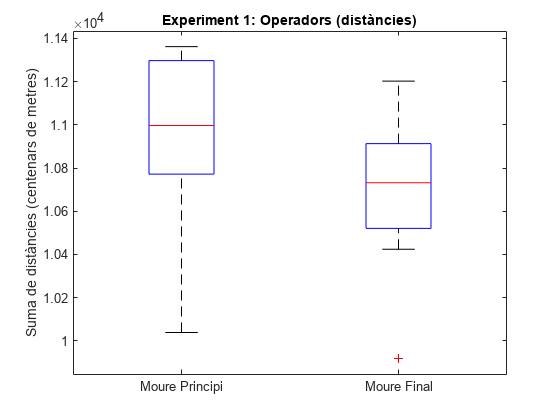

boxplot([Resultats1.MourePrincipi_Distancia_ Resultats1.MoureFinal_Distancia_], 'Labels',{'Moure Principi','Moure Final'})
title("Experiment 1: Operadors (distàncies)");
ylabel("Suma de distàncies (centenars de metres)");

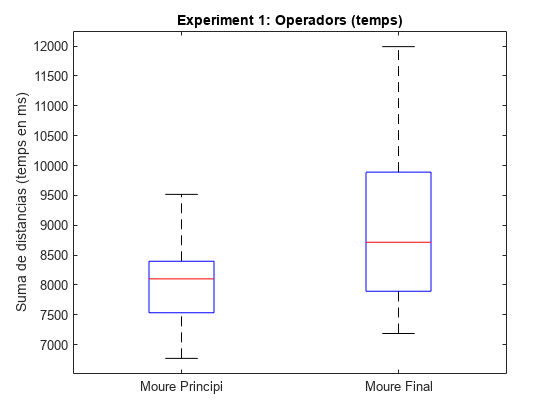


boxplot([Resultats1.MourePrincipi_Temps_ Resultats1.MoureFinal_Temps_], 'Labels',{'Moure Principi','Moure Final'})
title("Experiment 1: Operadors (temps)");
ylabel("Suma de distancias (temps en ms)");


mitjanes = [mean(Resultats1.MourePrincipi_Distancia_), mean(Resultats1.MoureFinal_Distancia_); mean(Resultats1.MourePrincipi_Temps_./1000) mean(Resultats1.MoureFinal_Temps_./1000)];
array2table(mitjanes, "VariableNames",{'Moure principi', 'Moure final'}, "RowNames", ["Suma de distàncies (centenars de metres)", "Temps (en s)"]);

t-test per comprobar les hipòtesis nules.

[h, p, ci, stats] = ttest(Resultats1.MourePrincipi_Distancia_, Resultats1.MoureFinal_Distancia_, "Alpha",0.05)

h = 1

p = 0.0061

ci =    80.0091
  358.5909


stats = struct with fields:
    tstat: 3.5615
       df: 9
       sd: 194.7152


[h2, p2, ci2, stats2] = ttest(Resultats1.MourePrincipi_Temps_ , Resultats1.MoureFinal_Temps_, "Alpha",0.05)

h2 = 1

p2 = 0.0448

ci2 = 1.0e+03 *

   -1.8133
   -0.0265


stats2 = struct with fields:
    tstat: -2.3292
       df: 9
       sd: 1.2489e+03


Experiment 2: Greedy vs Random

Resultats2 = readtable("Resultados_IA.xlsx", "Sheet","Experiment 2");

Resultats2 = 11×5 table
       Seed       GREEDY    RANDOM_MitjanaDe5_    TempsGreedy    TempsRandom_MitjanaDe5_
    __________    ______    __________________    ___________    _______________________

         10324    10656           10805              10886                10692         
         72719    10452           10572               7940                 9301         
     1.109e+05    10667           10598               9921                11070         
         31417    10293           10272               8603                11636         
      1.51e+05    10903           11080               9342                 9903         
     1.009e+05    10555           10769               9470                10618         
     2.012e+05    10834           11280              10613                 9969         
    

Resultats2 = Resultats2(1:10, 1:5)

Resultats2 = 10×5 table
       Seed       GREEDY    RANDOM_MitjanaDe5_    TempsGreedy    TempsRandom_MitjanaDe5_
    __________    ______    __________________    ___________    _______________________

         10324    10656           10805              10886                10692         
         72719    10452           10572               7940                 9301         
     1.109e+05    10667           10598               9921                11070         
         31417    10293           10272               8603                11636         
      1.51e+05    10903           11080               9342                 9903         
     1.009e+05    10555           10769               9470                10618         
     2.012e+05    10834           11280              10613                 9969         
    

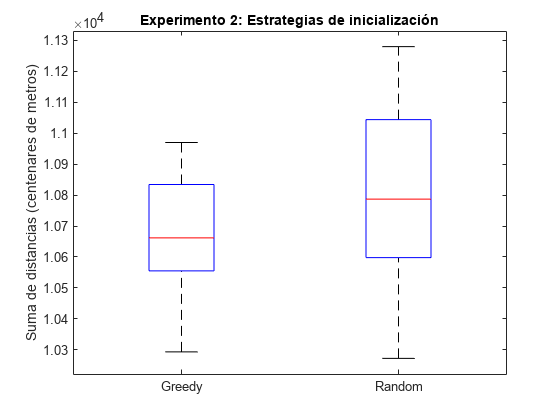


boxplot([Resultats2.GREEDY Resultats2.RANDOM_MitjanaDe5_], 'Labels',{'Greedy','Random'})
title("Experimento 2: Estrategias de inicialización")
ylabel("Suma de distancias (centenares de metros)")

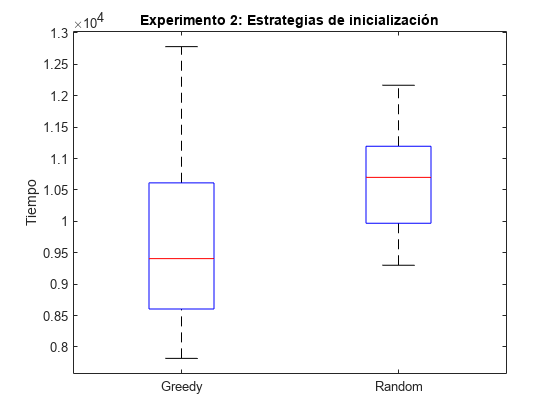


boxplot([Resultats2.TempsGreedy Resultats2.TempsRandom_MitjanaDe5_], 'Labels',{'Greedy','Random'})
title("Experimento 2: Estrategias de inicialización")
ylabel("Tiempo")


mitjanes = [mean(Resultats2.GREEDY), mean(Resultats2.RANDOM_MitjanaDe5_); mean(Resultats2.TempsGreedy./1000) mean(Resultats2.TempsRandom_MitjanaDe5_./1000)];

[h,p,interval,stats] = ttest(Resultats2.GREEDY, Resultats2.RANDOM_MitjanaDe5_,"Tail","right")

h = 0

p = 0.9839

interval =  -248.5386
       Inf


stats = struct with fields:
    tstat: -2.5293
       df: 9
       sd: 180.1656


[ht,pt,intervalT,statsT] = ttest(Resultats2.TempsGreedy, Resultats2.TempsRandom_MitjanaDe5_,"Tail","right")

ht = 0

pt = 0.9847

intervalT = 1.0e+03 *

   -1.8498
       Inf


statsT = struct with fields:
    tstat: -2.5615
       df: 9
       sd: 1.3311e+03


Experiment 3: Lambda-Experimentació

Resultats3 = readtable("Resultados_IA.xlsx", "Sheet","Experiment 3");

Resultats3 = Resultats3(1:10, 1:4)

Resultats3 = 10×4 table
       Seed       Lambda_0_5    Lambda_1    Lambda_2
    __________    __________    ________    ________

         20646      10548        10576       10872  
    1.4544e+05      10702        10702       10718  
     2.218e+05      10630        10630       10630  
         62832      10327        10516       10430  
      3.02e+05      10634        10634       10607  
     2.018e+05      10622        10377       10781  
     4.024e+05      10306        10298       10630  
         41804       9962         9962        9962  
    1.0271e+08      10795        10777       10867  
    9.7582e+05      10369        10369       10429  



boxplot([Experimento3.VarName2, Experimento3.VarName3, Experimento3.VarName4], 'Labels',{'Medio','Uno', 'Dos'})

Unable to resolve the name 'Experimento3.VarName2'.

title("Experimento 3: Lambda del heurístico")
ylabel("Suma de distancias (centenares de metros)")

[h1,p1,interval1,stats1] = ttest(Experimento3.VarName2, Experimento3.VarName3)
[h2,p2,interval2, stats2] = ttest(Experimento3.VarName2, Experimento3.VarName4)
[h3,p3,interval3,stats3] = ttest(Experimento3.VarName3, Experimento3.VarName4)

Experiment  4: Guerra d'Heurístics

Resultats4 = readtable("Resultados_IA.xlsx", "Sheet", "Experiment 4");

Resultats4 = Resultats4(1:10, 1:4)

Resultats4 = 10×4 table
       Seed       SumaDistancia    Entropia    Lambda_1
    __________    _____________    ________    ________

          5161        10752         10791       10813  
         36359         9926         10471        9904  
         55450        10738         11125       10692  
         15708        11133         11196       10979  
         75501        10759         10961       10617  
         50451        10348         10725       10288  
     1.006e+05        10378         10903       10792  
         10451        10220         10330       10235  
    2.5677e+07        10707         10986       10781  
    2.4396e+05        11162         11724       11280  


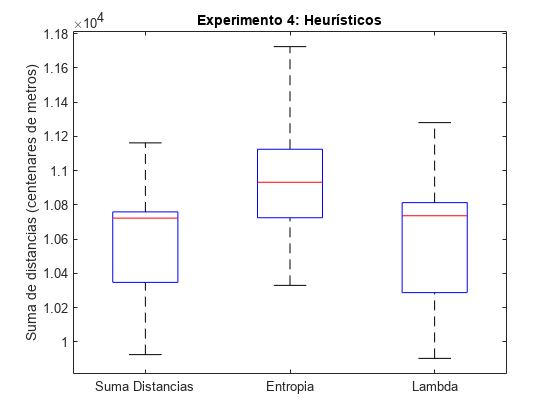


boxplot([Resultats4.SumaDistancia, Resultats4.Entropia, Resultats4.Lambda_1], 'Labels',{'Suma Distancias','Entropia', 'Lambda'})
title("Experimento 4: Heurísticos")
ylabel("Suma de distancias (centenares de metros)")


[h1,p1,interval1,stats1] = ttest(Resultats4.SumaDistancia, Resultats4.Entropia)

Unable to resolve the name 'Experimento4.SumaDistancia'.

[h2,p2,interval2,stats2] = ttest( Resultats4.Entropia, Resultats4.Lambda_1)
[h3,p3,interval3,stats3] = ttest(Resultats4.SumaDistancia, Resultats4.Lambda_1, "Tail", "Right")

Experiment 5

Resultats5 = readtable("Resultados_IA.xlsx", "Sheet", "Experiment 5", "ReadVariableNames",true);

Resultats5 = Resultats5(1:10, 1:9)

Resultats5 = 10×9 table
       Seed       x5000    x10000    x50000    x75000    x100000    x150000    x200000     HC  
    __________    _____    ______    ______    ______    _______    _______    _______    _____

         31092    12006    11273     10347     10248      10175      10202      10249     10907
    2.1828e+05    11975    11507     10633     10350      10232      10358      10185     10721
    3.3283e+05    11649    11155     10366     10193      10206      10054       9976     10955
         94371    12074    11400     10513     10105      10342      10083      10027     10709
    4.5313e+05    11559    11209     10229     10066       9960       9984      10126     104

Resultats5_2 = readtable("Resultados_IA.xlsx", "Sheet", "Experiment 5_2", "ReadVariableNames",true);

Resultats5_2 = 11×13 table
       Seed       k_1_l_1    k_1_l_0_01    k_1_l_0_0001    k_5_l_1    k_5_l_0_01    k_5_l_0_0001    k_25_l_1    k_25_l_0_01    k_25_l_0_0001    k_125_l_1    k_125_l_0_01    k_125_l_0_0001
    __________    _______    __________    ____________    _______    __________    ____________    ________    ___________    _____________    _________    ____________    ______________

          3482     13957       10675          10869         13625       10602          10557         13834         10723           10341          14138   

Resultats5_2 = Resultats5_2(1:10, 1:13)

Resultats5_2 = 10×13 table
       Seed       k_1_l_1    k_1_l_0_01    k_1_l_0_0001    k_5_l_1    k_5_l_0_01    k_5_l_0_0001    k_25_l_1    k_25_l_0_01    k_25_l_0_0001    k_125_l_1    k_125_l_0_01    k_125_l_0_0001
    __________    _______    __________    ____________    _______    __________    ____________    ________    ___________    _____________    _________    ____________    ______________

          3482     13957       10675          10869         13625       10602          10557         13834         10723           10341          14138   

Resultats5_3 = readtable("Resultados_IA.xlsx", "Sheet", "Experiment 5_3", "ReadVariableNames",true);

Resultats5_3 = 11×13 table
       Seed       k_15_L_0_001    k_15_L_0_0001    k_15_L_0_00001    k_20_L_0_001    k_20_L_0_0001    k_20_l_0_00001    k_25_L_0_001    k_25_L_0_0001    k_25_L_0_00001    k_30_L_0_001    k_30_L_0_0001    k_30_L_0_00001
    __________    ____________    _____________    ______________    ____________    _____________    ______________    ____________    _____________    ______________    ____________    _____________    ______________

          3482       10532            10645             10433           10710            102

Resultats5_3 = Resultats5_3(1:10, 1:13)

Resultats5_3 = 10×13 table
       Seed       k_15_L_0_001    k_15_L_0_0001    k_15_L_0_00001    k_20_L_0_001    k_20_L_0_0001    k_20_l_0_00001    k_25_L_0_001    k_25_L_0_0001    k_25_L_0_00001    k_30_L_0_001    k_30_L_0_0001    k_30_L_0_00001
    __________    ____________    _____________    ______________    ____________    _____________    ______________    ____________    _____________    ______________    ____________    _____________    ______________

          3482       10532            10645            10433            10710            102

Resultats5_4 = readtable("Resultados_IA.xlsx", "Sheet", "Experiment 5_4", "ReadVariableNames",true);

Resultats5_4 = 11×13 table
    Seed_Stiter     x50       x75       x100      x150      x200      x250      x300      x500      x750     x1000     x1250     x1500 
    ___________    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______

          7373       9989     10129      9994      9993     10038      9929      9987      9952     10054      9965     10096     10092
         51941       9899      9862      9985      9950      9834      9931      9894      9934      9786      9810      9

Resultats5_4 = Resultats5_4(1:10, 1:13)

Resultats5_4 = 10×13 table
    Seed_Stiter     x50      x75     x100     x150     x200     x250     x300     x500     x750     x1000    x1250    x1500
    ___________    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____

          7373      9989    10129     9994     9993    10038     9929     9987     9952    10054     9965    10096    10092
         51941      9899     9862     9985     9950     9834     9931     9894     9934     9786     9810     9818     9876
         79215      9870     9855 

Resultats5_5 = readtable("Resultados_IA.xlsx", "Sheet", "Experiment 5_5", "ReadVariableNames",true);

Resultats5_5 = 11×12 table
    Seed_Steps    x10000    x30000    x50000    x75000    x100000    x200000    x300000    x500000    x1000000    x2000000     HC  
    __________    ______    ______    ______    ______    _______    _______    _______    _______    ________    ________    _____

         19717    11612     10738     10208      10003      9763       9528       9226      9340         9262        9246     10411
         24516    12229     11337     10592      10078      9750       9607       9553      9567         9590        9583     11034
         27453    11988     10850   

Resultats5_5= Resultats5_5(1:10, 1:12)

Resultats5_5 = 10×12 table
    Seed_Steps    x10000    x30000    x50000    x75000    x100000    x200000    x300000    x500000    x1000000    x2000000     HC  
    __________    ______    ______    ______    ______    _______    _______    _______    _______    ________    ________    _____

         19717    11612     10738     10208     10003      9763       9528       9226       9340        9262        9246      10411
         24516    12229     11337     10592     10078      9750       9607       9553       9567        9590        9583      11034
         27453    11988     10850   

Experiment 6

Resultats6 = readtable("Resultados_IA.xlsx", "Sheet", "Experiment 6", "ReadVariableNames",true);

Resultats6 = 11×7 table
    Seed_Personas     x200     x300        x400          x500          x600          x700   
    _____________    ______    _____    __________    __________    __________    __________

          22467        8513    54690    1.9422e+05    5.0363e+05    9.7152e+05    2.2776e+06
     1.5827e+05       11482    45552     2.244e+05    5.4359e+05    1.0349e+06    2.3256e+06
     2.4137e+05        8150    43471    1.9055e+05    4.7652e+05    1.0841e+06    2.3881e+06
          68376       11151    42288    1.8047e+05    5.1309e+05    1.0666e+06    2.1641e+06
     3.2865e+05        9084    53715    1.6813e+05    4.0377e+05    9.7683e+05    2.0858e+06
     2.1961e+05        7716    50640    1.9337e+05     5.276e+05    1.0798e+06    2.27

Resultats6 = Resultats6(1:10, 1:7)

Resultats6 = 10×7 table
    Seed_Personas    x200     x300        x400          x500          x600          x700   
    _____________    _____    _____    __________    __________    __________    __________

          22467       8513    54690    1.9422e+05    5.0363e+05    9.7152e+05    2.2776e+06
     1.5827e+05      11482    45552     2.244e+05    5.4359e+05    1.0349e+06    2.3256e+06
     2.4137e+05       8150    43471    1.9055e+05    4.7652e+05    1.0841e+06    2.3881e+06
          68376      11151    42288    1.8047e+05    5.1309e+05    1.0666e+06    2.1641e+06
     3.2865e+05       9084    53715    1.6813e+05    4.0377e+05    9.7683e+05    2.0858e+06
     2.1961e+05       7716    50640    1.9337e+05     5.276e+05    1.0798e+06    2.2767e+06
 

Experiment 7

Resultats7_Dist = readtable("Resultados_IA.xlsx", "Sheet", "Experiment 7 Distancia", "ReadVariableNames",true);

Resultats7_Dist = Resultats7_Dist(1:10, 1:4)

Resultats7_Dist = 10×4 table
    Seed_Distancia    SumaDistancias    x_Coches    x_Coches_2
    ______________    ______________    ________    __________

       1.342e+05          10617          10544        10809   
      9.4533e+05          10969          10673        10427   
      1.4417e+06          11284          10510        10510   
      4.0841e+05          10971          10280        10244   
       1.963e+06          10761          10850        10850   
      1.3117e+06          10680          10240        10284   
      2.6156e+06          10571          10467        10497   
      2.7173e+05          11221          10925        10851   
       6.676e+08          10894          10369        10528   
      6.3429e+06          11077          10582        10088   


Resultats7_Temps = readtable("Resultados_IA.xlsx", "Sheet", "Experiment 7 Temps", "ReadVariableNames",true);

Resultats7_Temps = Resultats7_Temps(1:10, 1:4)

Resultats7_Temps = 10×4 table
    Seed_Temps    SumaDistancias    x_Coches    x_Coches_2
    __________    ______________    ________    __________

     1.342e+05        11857          26789        27071   
    9.4533e+05        11910          23207        25343   
    1.4417e+06        10257          24719        24605   
    4.0841e+05         9775          25273        25770   
     1.963e+06         9490          18516        18420   
    1.3117e+06         9615          26515        27921   
    2.6156e+06        11023          24021        22885   
    2.7173e+05        10899          23870        25090   
     6.676e+08        11129          27053        22544   
    6.3429e+06         8966          22286        28151   


Resultats7_Cotxes = readtable("Resultados_IA.xlsx", "Sheet", "Experiment 7 Cotxes", "ReadVariableNames",true);

Resultats7_Cotxes = Resultats7_Cotxes(1:10, 1:4)

Resultats7_Cotxes = 10×4 table
    Seed_Cotxes    SumaDistancias    x_Coches    x_Coches_2
    ___________    ______________    ________    __________

     1.342e+05           91             55           54    
    9.4533e+05           90             56           53    
    1.4417e+06           86             57           57    
    4.0841e+05           92             54           54    
     1.963e+06           95             56           56    
    1.3117e+06           92             56           55    
    2.6156e+06           87             54           54    
    2.7173e+05           90             56           56    
     6.676e+08           92             52           55    
    6.3429e+06           91             55           53    


Experiment 8

Resultats8_Dist = readtable("Resultados_IA.xlsx", "Sheet", "Experiment 8 Distancia", "ReadVariableNames",true);

Resultats8_Dist = Resultats8_Dist(1:10, 1:4)

Resultats8_Dist = 10×4 table
    Seed_Distancia    SumaDistancias    x_Coches    x_Coches_2
    ______________    ______________    ________    __________

       1.342e+05           9570          10662        10654   
      9.4533e+05           9406          10876        10301   
      1.4417e+06           9567          10984        10899   
      4.0841e+05           9332          10440         9946   
       1.963e+06           9466          10373        10413   
      1.3117e+06           9327          10656        10520   
      2.6156e+06           9361          10466        10619   
      2.7173e+05           9508          10575        11012   
       6.676e+08           9392          10862        10700   
      6.3429e+06           9264          10643        10170   


Resultats8_Temps = readtable("Resultados_IA.xlsx", "Sheet", "Experiment 8 Temps", "ReadVariableNames",true);

Resultats8_Temps = Resultats8_Temps(1:10, 1:4)

Resultats8_Temps = 10×4 table
    Seed_Temps    SumaDistancias    x_Coches    x_Coches_2
    __________    ______________    ________    __________

     1.342e+05         2029           2025         2188   
    9.4533e+05         1792           2409         2158   
    1.4417e+06         1835           2461         2141   
    4.0841e+05         1773           1989         1951   
     1.963e+06         1544           1915         1850   
    1.3117e+06         1596           2035         1877   
    2.6156e+06         1510           1938         1843   
    2.7173e+05         1592           1975         1999   
     6.676e+08         1747           1922         1984   
    6.3429e+06         1530           1871         1948   


Resultats8_Cotxes = readtable("Resultados_IA.xlsx", "Sheet", "Experiment 8 Cotxes", "ReadVariableNames",true);

Resultats8_Cotxes = Resultats8_Cotxes(1:10, 1:4)

Resultats8_Cotxes = 10×4 table
    Seed_Cotxes    SumaDistancias    x_Coches    x_Coches_2
    ___________    ______________    ________    __________

     1.342e+05           61             52           50    
    9.4533e+05           62             49           50    
    1.4417e+06           58             50           54    
    4.0841e+05           58             51           48    
     1.963e+06           62             50           50    
    1.3117e+06           60             49           51    
    2.6156e+06           60             49           50    
    2.7173e+05           57             50           52    
     6.676e+08           52             50           49    
    6.3429e+06           61             51           48    


Experiment 9

Resultats9_1 = readtable("Resultados_IA.xlsx", "Sheet", "Experiment 9", "ReadVariableNames",true);

Resultats9_1 = Resultats9_1(1:10, 1:11)

Resultats9_1 = 10×11 table
    Seed_Persones    x200    x250    x300    x350    x400    x450    x500    x550    x600    x650
    _____________    ____    ____    ____    ____    ____    ____    ____    ____    ____    ____

           32764      47      61      70      87      96     110     119     129     144     154 
       2.308e+05      49      60      75      85      98     107     121     131     141     155 
      3.5199e+05      47      66      74      87      96     105     126     137     144     154 
           99711      50      60      70      80      96     106     118     131     144     157 
      4.79

Resultats9_2 = readtable("Resultados_IA.xlsx", "Sheet", "Experiment 9_2", "ReadVariableNames",true);

Resultats9_2 = Resultats9_2(1:10, 1:4)

Resultats9_2 = 10×4 table
    Seed_Distancia    SumaDistancias    x_Coches    x_Temps
    ______________    ______________    ________    _______

           32764          10030            48        2047  
       2.308e+05          10441            48        1842  
      3.5199e+05          10388            49        1792  
           99711           9831            48        1720  
      4.7927e+05          10628            47        2109  
      3.2025e+05          10111            49        1637  
      6.3859e+05          10734            49        1835  
           66341          10047            48        1801  
     -2.3746e+07          10816            46        2359  
      1.5486e+06          10325            46        1975  


Resultats9_3 = readtable("Resultados_IA.xlsx", "Sheet", "Experiment 9_3", "ReadVariableNames",true);

Resultats9_3 = Resultats9_3(1:10, 1:4)

Resultats9_3 = 10×4 table
    Seed_Distancia    SumaDistancias    x_Coches    x_Temps
    ______________    ______________    ________    _______

           32764          10418            49        2291  
       2.308e+05          10934            50        2067  
      3.5199e+05          10228            47        1881  
           99711          10123            49        1774  
      4.7927e+05          10283            51        1772  
      3.2025e+05          10586            49        1819  
      6.3859e+05          10961            53        1839  
           66341          10242            50        1932  
     -2.3746e+07          10165            50        1821  
      1.5486e+06          10114            46        2067  





x = [200:100:700];
y = [9147.1, 50254.5, 193824.2, 481523.8, 1039274.25, 2263407];
g = polyfit(x, y, 2);
g2 = polyfit(x, y, 3);
g3 = polyfit(x, y, 4);
%f = fit(x', y', "exp1");
x2 = linspace(200, 700, 1000);
y2 = polyval(g, x2);
y3 = polyval(g2, x2);
y4 = polyval(g3, x2);
scatter(x, y);
hold on
plot(x2, y3, x2, y2, x2, y4);
legend("Puntos reales", "Cúbica", "Cuadrática", "Grado 4");
hold off

Sr2 = y - polyval(g, x);
Sr3 = y - polyval(g2, x);
Sr4 = y - polyval(g3, x);

polyval(g2, 700);
polyval(g3, 700);

Sr = [sum(Sr2.^2)/2 sum(Sr3.^2) sum(Sr4.^2)]

Sr = 1.0e+10 *

    3.0713    0.4630    0.0138


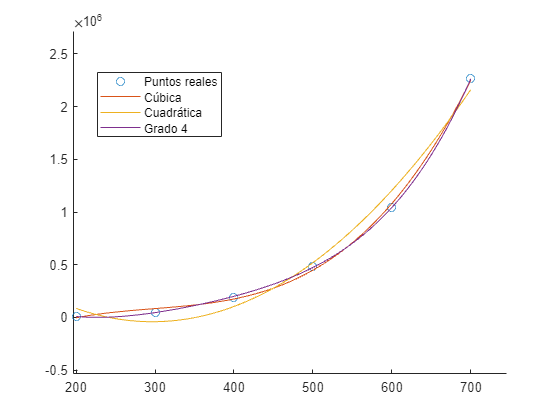

xlim([196 746])
ylim([-582311 2717689])
legend("Position", [0.17381,0.67341,0.22321,0.15595])

%plot(f);